clc;
close all;
clearvars;
%%Preg1
%Constante de propagación
R=2.5;
C=12*10^(-12);
L=1.8*10^(-6);
c=3*10^8;
G=10^(-7);
f=100*10^6;
w=2*pi*f;
Z=R+1i*w*L

Z = 2.5000e+00 + 1.1310e+03i

Y=G+1i*w*C

Y = 0.0000 + 0.0075i

%número de onda gamma=y
y=sqrt(-Z*Y)

y = 2.9202 - 0.0032i

%betha -> constante de propagación
betha=real(y)

betha = 2.9202

%alpha -> cosntante de atenuación
alpha=imag(y)*-1

alpha = 0.0032

%velocidad de fase
vf=w/betha

vf = 2.1517e+08

vf1=vf/c

vf1 = 0.7172

%impedancia característica
Z0=sqrt(Z/Y)

Z0 = 3.8730e+02 - 4.2549e-01i

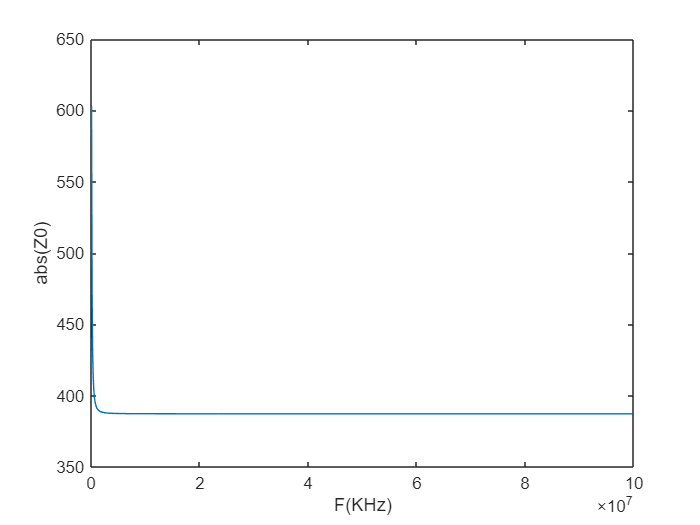

%%Graficar el abs(Z0) vs F
F=100000:100000:f;
Zg=R+1i.*F*2*pi*L;
Yg=G+1i.*F*2*pi*C;
Z0g=abs(sqrt(Zg./Yg));
plot(F,Z0g)
ylabel("abs(Z0)")
xlabel("F(KHz)")